# TP 1 : Spectral characterization 

## I. Frequency filtering  

1)

img = imread('TP01I01.jpg');
figure(1);
subplot(2,4,1);
imshow(img);
img_d=double(img);


colormap(gray(256));
f_spectrum = fftshift(fft2(img));
subplot(2,4,2);
imagesc(log(abs(f_spectrum)));
axis equal;
axis off;

subplot(2,4,3);
[x,y]=size(f_spectrum);
f_spectrum_filtre=zeros(x,y);
filtre=50;
for i=1:x
    for j=1:y
        if(i>filtre && i<x-filtre && j>filtre && j<y-filtre)
            f_spectrum_filtre(i,j) =f_spectrum(i,j);
        end
    end
end
imagesc(log(abs(f_spectrum_filtre)));
axis equal;
axis off;

2)

Voici les 3 images que l'on obtient après les diverses transformations et filtrage.

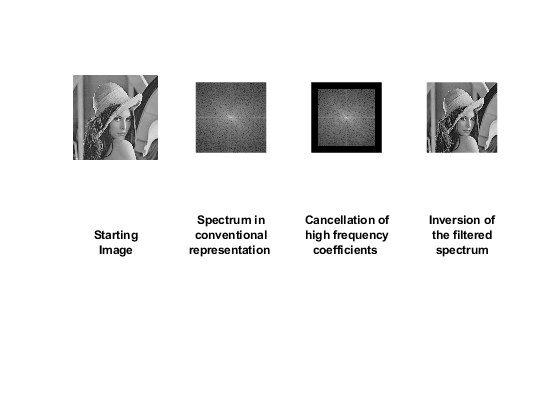

img_inv_f_spectrum= abs(ifft2(fftshift(f_spectrum_filtre)));
subplot(2,4,4);
imagesc(img_inv_f_spectrum);
axis equal;
axis off;
subplot(2,4,5);
title({"Starting" "Image"})
axis off;
subplot(2,4,6);
title({"Spectrum in" "conventional" "representation "})
axis off;
subplot(2,4,7);
title({"Cancellation of" "high frequency" "coefficients "})
axis off;
subplot(2,4,8);
title({"Inversion of" "the filtered" "spectrum"})
axis off;

L'erreur quadratique moyenne entre l'image de base et l'image après la transformé inverse est la suivante:

rmse = immse(img_d, img_inv_f_spectrum)

rmse = 3.1142

3)

Le graphe sur l'evolution de l'erreur moyenne quadratique est le suivant:

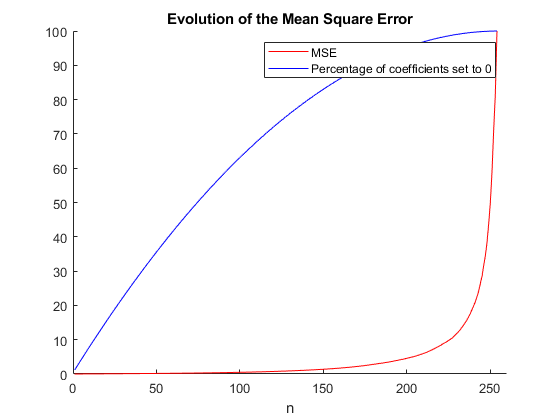

n=1;
n_tot=[];
nb_zeros=[];
nb_zero_tot=0;
error=[];
f_spectrum2=f_spectrum;
longueur_image = size(img_d,1);
largeur_image = size(img_d,2);

while (n < largeur_image/2-1)
            f_spectrum2(1:n,:)=0;
            f_spectrum2(longueur_image-n:longueur_image,:)=0;
            f_spectrum2(:,1:n)=0;
            f_spectrum2(:,largeur_image-n:largeur_image)=0;
            img_filtered = abs(ifft2(fftshift(f_spectrum2)));
            rmse = immse(img_d, img_filtered) ;
            error = [error rmse];
            nbr_zeros = length(find(f_spectrum2==0));
            nb_zeros=[nb_zeros nbr_zeros];
            n_tot=[n_tot n];
            n=n+1;
            
end
%Mise en pourcentage
max_error=max(error);
error_pct=(error/max_error)*100;
nb_zeros_pct=(nb_zeros/max(nb_zeros))*100;
figure(2);
hold on;
plot (n_tot,error_pct,'r');
plot (n_tot,nb_zeros_pct,'b');
hold off;
title("Evolution of the Mean Square Error")
legend('MSE','Percentage of coefficients set to 0')
xlabel('n') 
axis([0 n+5 0 100]);

## II Characterization

1)

chemin_fic='bibimage\';
d = dir(strcat(chemin_fic,'*.jpg'));
nbimg=length(find([d.isdir]==0));

signature=zeros(nbimg,18);
for i=1:nbimg
   field = struct2cell(d(i));
   clear img;
   img=imread(strcat(chemin_fic,field{1}));
   img_conv = rgb2gray(img);
   spectre= fftshift(fft2(img_conv));
   aff_spectre=log(abs(spectre)+1);
   % pour les lignes de 1 à 50
   signature(i,1)= caracterisation (aff_spectre,1,50,1,50);
   signature(i,2)= caracterisation (aff_spectre,1,50,51,75);
   signature(i,3)= caracterisation (aff_spectre,1,50,76,100);
   signature(i,4)= caracterisation (aff_spectre,1,50,101,125);
   signature(i,5)= caracterisation (aff_spectre,1,50,126,150);
   signature(i,6)= caracterisation (aff_spectre,1,50,151,200);
   % pour les lignes de 51 à 75
   signature(i,7)= caracterisation (aff_spectre,51,75,1,50);
   signature(i,8)= caracterisation (aff_spectre,51,75,51,75);
   signature(i,9)= caracterisation (aff_spectre,51,75,76,100);
   signature(i,10)= caracterisation (aff_spectre,51,75,101,125);
   signature(i,11)= caracterisation (aff_spectre,51,75,126,150);
   signature(i,12)= caracterisation (aff_spectre,51,75,151,200);
   % pour les lignes de 76 à 100
   signature(i,13)= caracterisation (aff_spectre,51,75,1,50);
   signature(i,14)= caracterisation (aff_spectre,51,75,51,75);
   signature(i,15)= caracterisation (aff_spectre,51,75,76,100);
   signature(i,16)= caracterisation (aff_spectre,51,75,101,125);
   signature(i,17)= caracterisation (aff_spectre,51,75,126,150);
   signature(i,18)= caracterisation (aff_spectre,51,75,151,200);
end

On commence par établir pour chaque image dans notre base un vecteur de caractéristiques caractérisant la

texture. On obtient la matrice 50x18 suivante (pour 50 images et 18 zones prédéfinies ou feature)

disp(signature)

   1.0e+04 *

  Columns 1 through 12

    1.8629    0.9761    1.0080    1.0234    0.9963    1.8775    0.9594    0.5016    0.5445    0.5576    0.5239    0.9805
    1.7688    0.9667    1.0251    1.0250    0.9702    1.7741    0.9485    0.5172    0.5611    0.5688    0.5194    0.9466
    1.6397    0.9515    1.0632    1.0904    0.9622    1.6519    0.8538    0.4913    0.5564    0.5696    0.4989    0.8575
    1.7532    0.9663    1.0854    1.0648    0.9613    1.7490    0.9187    0.5135    0.5839    0.5714    0.5075    0.9229
    1.7132    0.8150    0.8531    0.8908    0.8658    1.7724    0.9515    0.4353    0.4443    0.4854    0.4811    1.0034
    1.6978    0.7964    0.8094    0.8254    0.8344    1.7474    0.9431    0.4161    0.4301    0.4705    0.4932    1.0393
    1.6428    0.8009    0.7941    0.8005    0.7933    1.6077    1.0070    0.4738    0.4342    0.4296    0.4271    0.9146
    1.9649    0.9742    0.9514    0.9380    0.9793    1.9702    1.0146    0.5040    0.4800    0.4950    0.5232    1

On effectue un test de similarité sur toutes les images de notre base entre elles à l'aide de la distance Manhattan entre les vecteurs des images. L'image avec la distance la plus faible sera la plus ressemblante.

%Similarité de toutes les images :
for num_im= 1 : nbimg
    [m ,i]= similaire (num_im,signature,nbimg);
    disp(['L image ' num2str(num_im) ' resemble le plus a l image ' num2str(i) ]);
end

L image 1 resemble le plus a l image 32
L image 2 resemble le plus a l image 42
L image 3 resemble le plus a l image 48
L image 4 resemble le plus a l image 13
L image 5 resemble le plus a l image 6
L image 6 resemble le plus a l image 5
L image 7 resemble le plus a l image 33
L image 8 resemble le plus a l image 9
L image 9 resemble le plus a l image 8
L image 10 resemble le plus a l image 36
L image 11 resemble le plus a l image 42
L image 12 resemble le plus a l image 26
L image 13 resemble le plus a l image 4
L image 14 resemble le plus a l image 43
L image 15 resemble le plus a l image 35
L image 16 resemble le plus a l image 45
L image 17 resemble le plus a l image 37
L image 18 resemble le plus a l image 36
L image 19 resemble le plus a l image 30
L image 20 resemble le plus a l image 17
L image 21 resemble le plus a l image 41
L image 22 resemble le plus a l image 42
L image 23 resemble le plus a l image 24
L image 24 resemble le plus a l image 23
L image 25 resemble le plus a 